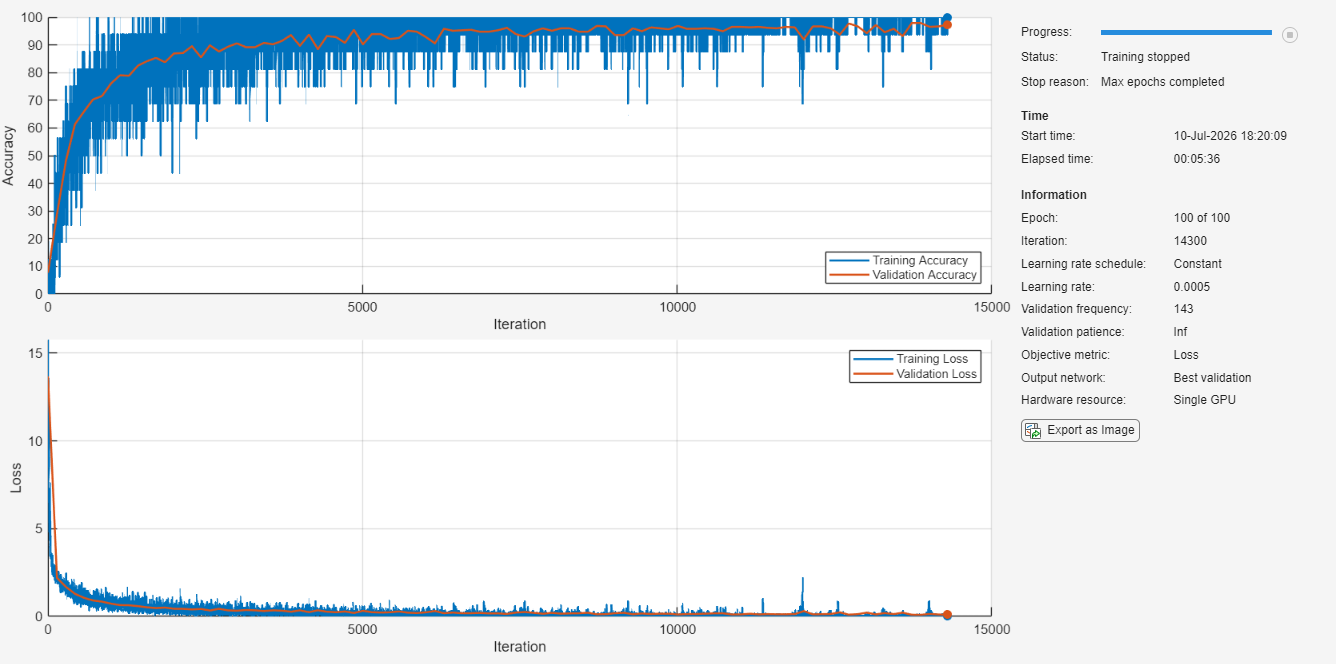

clearvars
clc

% ------------------------------------------------------------
% Einstellungen
% ------------------------------------------------------------

bildpfad = ...
    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt" + ...
    "\09_Trainingsdaten\AusgeschnittenFuerTraining" + ...
    "\99_Trainingsdatensaetze" + ...
    "\03_13Kat_Alle Schilder" + ...
    "\Geschwindigkeitsbegrenzung_100" + ...
    "\Geschwindigkeitsbegrenzung_100_136.jpg";

load("netGAP32_Lauf_01.mat");

net = net; % falls nötig

% ------------------------------------------------------------
% Einzelbild-Datastore
% ------------------------------------------------------------

imdsEinzelbild = imageDatastore(bildpfad);

augEinzelbild = augmentedImageDatastore( ...
    [48 48], ...
    imdsEinzelbild, ...
    ColorPreprocessing="none", ...
    OutputSizeMode="resize" ...
);

% Bild über exakt dieselbe MATLAB-Pipeline auslesen
miniBatch = read(augEinzelbild);

I_MATLAB = miniBatch.input{1};

fprintf("----------------------------------------\n");

----------------------------------------


fprintf("MATLAB-Bild nach Datastore-Verarbeitung\n");

MATLAB-Bild nach Datastore-Verarbeitung


fprintf("----------------------------------------\n");

----------------------------------------



fprintf("Datentyp: %s\n", class(I_MATLAB));

Datentyp: uint8


fprintf("Bildgröße: %s\n", mat2str(size(I_MATLAB)));

Bildgröße: [48 48 3]


fprintf("Minimum: %g\n", double(min(I_MATLAB(:))));

Minimum: 0


fprintf("Maximum: %g\n", double(max(I_MATLAB(:))));

Maximum: 158



% ------------------------------------------------------------
% MATLAB-Vorhersage
% ------------------------------------------------------------

X_MATLAB = single(I_MATLAB);

scoresMATLAB = predict(net, X_MATLAB);

if isa(scoresMATLAB, "dlarray")
    scoresMATLAB = extractdata(scoresMATLAB);
end

scoresMATLAB = squeeze(gather(scoresMATLAB));

[~, predictedIndex] = max(scoresMATLAB);

fprintf("\nVorhergesagter Klassenindex ab 0: %d\n", ...
    predictedIndex - 1);


Vorhergesagter Klassenindex ab 0: 4



disp(scoresMATLAB);

    0.0000
    0.0000
    0.0000
    0.0000
    1.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000




% ------------------------------------------------------------
% Für Python speichern
% ------------------------------------------------------------

save( ...
    "unabhaengiger_bildvergleich.mat", ...
    "I_MATLAB", ...
    "scoresMATLAB", ...
    "bildpfad" ...
);